# Example 4.1

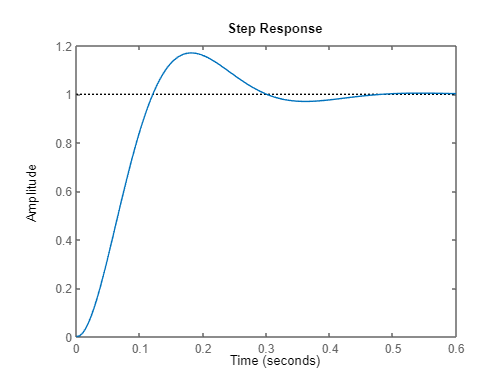

clc;
clear all;
s = tf('s');
KA = 80;
G1 = 5000/(s+1000);
G2 = 1/(s*(s+20));
M = feedback(series(KA*G1,G2),1);
step(M)

## Step response with respect to W(s)

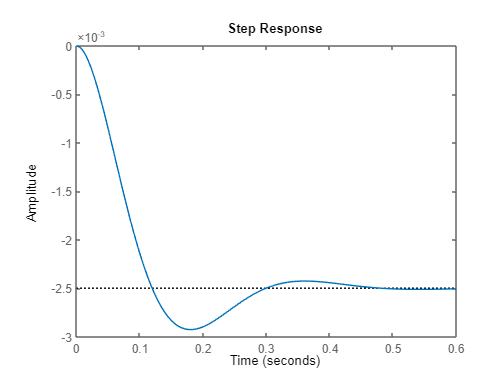

clc;
clear all;
s = tf('s');
KA = 80;
G1 = 5000/(s+1000);
G2 = 1/(s*(s+20));
Mw = (-1) * feedback(G2, KA*G1);
step(Mw)

## Example 4.2

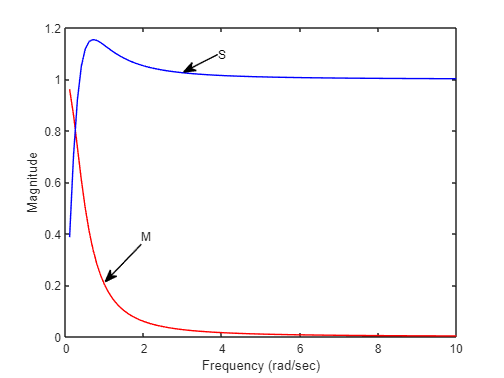

clc;
clear all;
w = 0.1:0.1:10;
M = abs(0.25./((j*w).^2+j*w+0.25));
SMK = abs((j*w .* (j*w + 1))./((j*w).^2 + j*w +0.25));
plot(w,M,'r',w,SMK,'b');
xlabel('Frequency (rad/sec)');
ylabel('Magnitude');

annotation('textarrow',[0.2804 0.2089],[0.3538 0.2548],'String','M')
annotation('textarrow',[0.4321 0.3643],[0.8561 0.8095],'String','S')

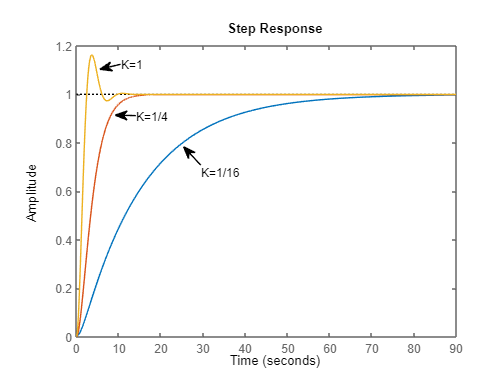

clc;
clear all;
s = tf('s');
S = (s*(s+1))/(s^2+s+0.25);
M1 = 0.0625/(s^2+s+0.0625);
M2 = 0.25/(s^2+s+0.25);
M3 = 1/(s^2+s+1);
step(M1);
hold on;
step(M2);
step(M3);

annotation('textarrow',[0.3982 0.3643],[0.5633 0.6119],'String','K=1/16')
annotation('textarrow',[0.2696 0.2286],[0.6942 0.6952],'String','K=1/4')
annotation('textarrow',[0.2393 0.1982],[0.83 0.8167],'String','K=1')

## Example 4.3

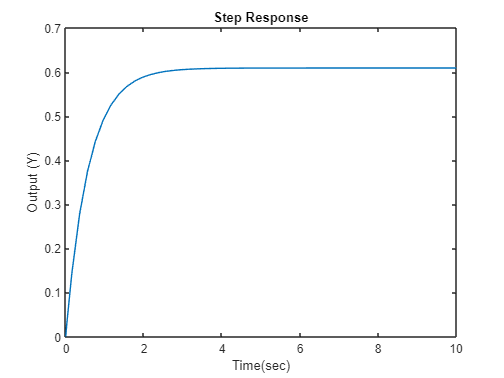

clc;
clear all;
clf;
open_system('Example_4_3.slx');
ans = sim('Example_4_3.slx');
plot(ans.Output.Time,ans.Output.Data);
ylabel('Output (Y)');
xlabel('Time(sec)');
title('Step Response');

## Example 4.4

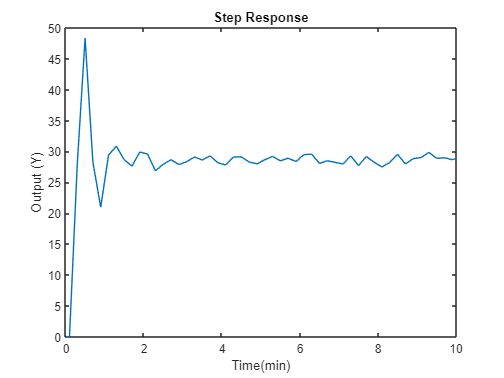

clc;
clear all;
clf;
open_system('Example_4_4.slx');
ans = sim('Example_4_4.slx');
plot(ans.Y.Time,ans.Y.Data);
ylabel('Output (Y)');
xlabel('Time(min)');
title('Step Response');

## Example 4.5

clc;
clear all;
clf;
s=tf('s');
G1 = 1/(s+7);
G2= 1/(s^2+2*s+3);
G3= 1/(s+4);
G4= 1/s;
G5= 5/(s+7);
G6=1/(s^2+5*s+10);
G7=3/(s+2);
G8= 1/(s+6);
G9=1;
T1= append(G1,G2,G3,G4,G5,G6,G7,G8,G9);
Q= [1 -2 -5 9
    2 1 8 0
    3 1 8 0
    4 1 8 0
    5 3 4 -6
    6 7 0 0
    7 3 4 -6
    8 7 0 0];
input = 9;
output= 7;
Ts= connect(T1,Q,input,output);
T = tf(Ts)

T =
 
                              
  6 s^7 + 132 s^6 + 1176 s^5  
                              
          + 5640 s^4          
                              
          + 1.624e04 s^3      
                              
          + 2.857e04 s^2      
                              
          + 2.988e04 s        
                              
                    + 1.512e04
                              
  ----------------------------
                              
  s^10 + 33 s^9 + 466 s^8     
                              
          + 3720 s^7          
                              
          + 1.867e04 s^6      
                              
          + 6.182e04 s^5      
                              
          + 1.369e05 s^4      
                              
          + 1.981e05 s^3      
                              
          + 1.729e05 s^2      
                              
          + 6.737e04 s        
                              
                    - 1.044e04
  